  
% Origional Model
% Where I implemented Tmax and Tmin to predict the local average temp.

ds = datastore("3008318mod.csv","TextType","string","DatetimeType","datetime");

preview(ds);
ds.ReadSize;
data1 = read(ds);
%w = importfileTemp("3008318mod.csv")
WS = readall(ds);
% Remove Variables
ws = removevars(WS,["AWND","AWND_1","AWND_2","AWND_3","AWND_4","AWND_5","AWND_6","AWND_7",...
    "DATE_1","DATE_2","DATE_3","DATE_4","DATE_5","DATE_6","DATE_7","FMTM","FMTM_1","FMTM_2","FMTM_3","FMTM_4","FMTM_5","FMTM_6","FMTM_7",...
    "MDPR","MDPR_1","MDPR_2","MDPR_3","MDPR_4","MDPR_5","MDPR_6","MDPR_7","NAME","NAME_1","NAME_2","NAME_3","NAME_4","NAME_5","NAME_6","NAME_7",...
    "PGTM","PGTM_1","PGTM_2","PGTM_3","PGTM_4","PGTM_5","PGTM_6","PGTM_7","PRCP",...
    "PRCP_1","PRCP_2","PRCP_3","PRCP_4","PRCP_5","PRCP_6","PRCP_7","PSUN","PSUN_1","PSUN_2","PSUN_3","PSUN_4",...
    "PSUN_5","PSUN_6","PSUN_7","SNOW","SNOW_1","SNOW_2","SNOW_3","SNOW_4","SNOW_5","SNOW_6","SNOW_7","SNWD",...
    "SNWD_1","SNWD_2","SNWD_3","SNWD_4","SNWD_5","SNWD_6","SNWD_7","TSUN","TSUN_1","TSUN_2","TSUN_3","TSUN_4","TSUN_5","TSUN_6","TSUN_7",...
    "WDF2","WDF2_1","WDF2_2","WDF2_3","WDF2_4","WDF2_5","WDF2_6","WDF2_7","WDF5","WDF5_1","WDF5_2","WDF5_3","WDF5_4","WDF5_5","WDF5_6","WDF5_7",...
    "WESD","WESD_1","WESD_2","WESD_3","WESD_4","WESD_5","WESD_6","WESD_7","WSF5","WSF5_1","WSF5_2","WSF5_3","WSF5_4","WSF5_5","WSF5_6","WSF5_7",...
    "WT01","WT01_1","WT01_2","WT01_3","WT01_4","WT01_5","WT01_6","WT01_7","STATION","STATION_1","STATION_2","STATION_3","STATION_4","STATION_5","STATION_6","STATION_7",...
    "WSF2","WSF2_1","WSF2_2","WSF2_3","WSF2_4","WSF2_5","WSF2_6","WSF2_7","WT02","WT02_1","WT02_2","WT02_3","WT02_4","WT02_5","WT02_6","WT02_7",...
    "WT03","WT03_1","WT03_2","WT03_3","WT03_4","WT03_5","WT03_6","WT03_7","WT04","WT04_1","WT04_2","WT04_3","WT04_4","WT04_5","WT04_6","WT04_7",...
    "WT05_1","WT05_2","WT05_3","WT05_4","WT05_5","WT05_6","WT05_7","WT06_1","WT06_2","WT06_3","WT06_4","WT06_5","WT06_6","WT06_7","WT07_1","WT07_2",...
    "WT07_3","WT07_4","WT07_5","WT07_6","WT07_7","WT08_1","WT08_2","WT08_3","WT08_4","WT08_5","WT08_6","WT08_7","WT09_1","WT09_2","WT09_3","WT09_4",...
    "WT09_5","WT09_6","WT09_7","WT10_1","WT10_2","WT10_3","WT10_4","WT10_5","WT10_6","WT10_7","WT11_1","WT11_2","WT11_3","WT11_4","WT11_5","WT11_6",...
    "WT11_7","WT13_1","WT13_2","WT13_3","WT13_4","WT13_5","WT13_6","WT13_7","WT14_1","WT05","WT06","WT07","WT08","WT09","WT10","WT11","WT13","WT14","WT15","WT16","WT17","WT18","WT19","WT21","WT22",...
    "WT14_2","WT14_3","WT14_4","WT14_5","WT14_6","WT14_7","WT15_1","WT15_2","WT15_3","WT15_4","WT15_5","WT15_6","WT15_7","WT16_1","WT16_2","WT16_3",...
    "WT16_4","WT16_5","WT16_6","WT16_7","WT17_1","WT17_2","WT17_3","WT17_4","WT17_5","WT17_6","WT17_7","WT18_1","WT18_2","WT18_3","WT18_4","WT18_5",...
    "WT18_6","WT18_7","WT19_1","WT19_2","WT19_3","WT19_4","WT19_5","WT19_6","WT19_7","WV01_1","WV01_2","WV01_3","WV01_4","WV01_5","WV01_6","WV01_7",...
    "WV03_1","WV03_2","WV03_3","WV03_4","WV03_5","WV03_6","WV03_7","WT21_1","WT21_2","WT21_3","WT21_4","WT21_5","WT21_6","WT21_7","WT22_1","WT22_2",...
    "WT22_3","WT22_4","WT22_5","WT22_6","WT22_7","WV03","WV01"...
    ]);
ws.TAVG = (ws.TMAX + ws.TMIN)./2;ws.TAVG_1 = (ws.TMAX_1 + ws.TMIN_1)./2;ws.TAVG_2 = (ws.TMAX_2 + ws.TMIN_2)./2;
ws.TAVG_3 = (ws.TMAX_3 + ws.TMIN_3)./2;ws.TAVG_4 = (ws.TMAX_4 + ws.TMIN_4)./2;ws.TAVG_5 = (ws.TMAX_5 + ws.TMIN_5)./2;
ws.TAVG_6 = (ws.TMAX_6 + ws.TMIN_6)./2;ws.TAVG_7 = (ws.TMAX_7 + ws.TMIN_7)./2;

% Training Data
ws1 = ws(1:1534,:)

ws1 = 1534×25 table
       DATE        TAVG     TMAX    TMIN    TAVG_1    TMAX_1    TMIN_1    TAVG_2    TMAX_2    TMIN_2    TAVG_3    TMAX_3    TMIN_3    TAVG_4    TMAX_4    TMIN_4    TAVG_5    TMAX_5    TMIN_5    TAVG_6    TMAX_6    TMIN_6    TAVG_7    TMAX_7    TMIN_7
    ___________    _____    ____    ____    ______    ______    ______    ______    ______    ______    ______    

% Test Data
ws2 = ws(1535:2191,:);


%   FAIRBANKS INTERNATIONAL AIRPORT, AK US
% 1 HUNTSVILLE MUNICIPAL AIRPORT, TX US
% 2 KANSAS CITY DOWNTOWN AIRPORT, MO US
% 3 ISLIP LI MACARTHUR AIRPORT, NY US
% 4 KALISPELL GLACIER AIRPORT, MT US
% 5 CARLSBAD MCCLELLAN PALOMAR AIRPORT, CA US
% 6 HONOLULU INTERNATIONAL AIRPORT, HI US
% 7 ANDERSON FAA AIRPORT, SC US


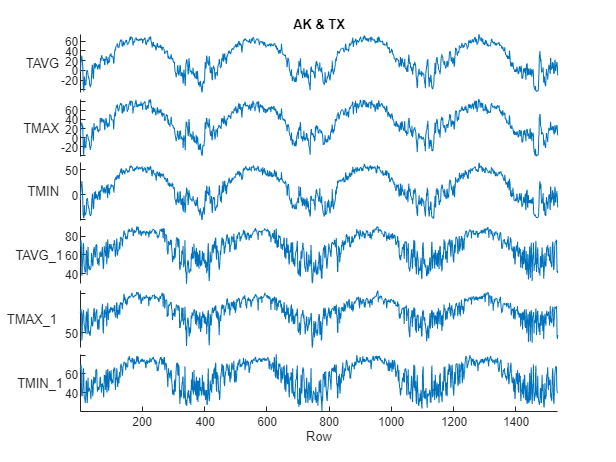

 
%   FAIRBANKS INTERNATIONAL AIRPORT, AK US
% 1 HUNTSVILLE MUNICIPAL AIRPORT, TX US
stackedplot(ws1(:,2:7))
title("AK & TX")

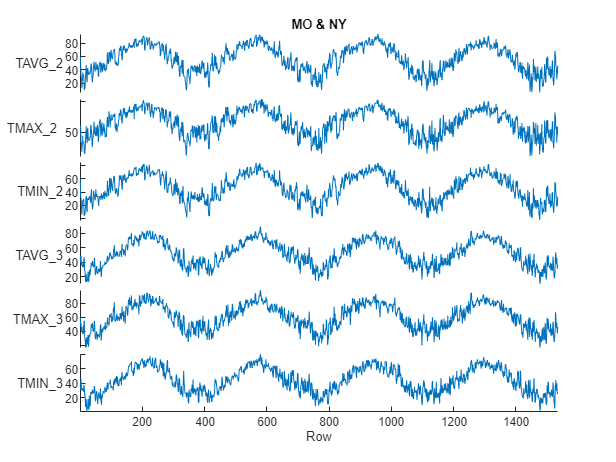

% 2 KANSAS CITY DOWNTOWN AIRPORT, MO US
% 3 ISLIP LI MACARTHUR AIRPORT, NY US
stackedplot(ws1(:,8:13))
title("MO & NY")

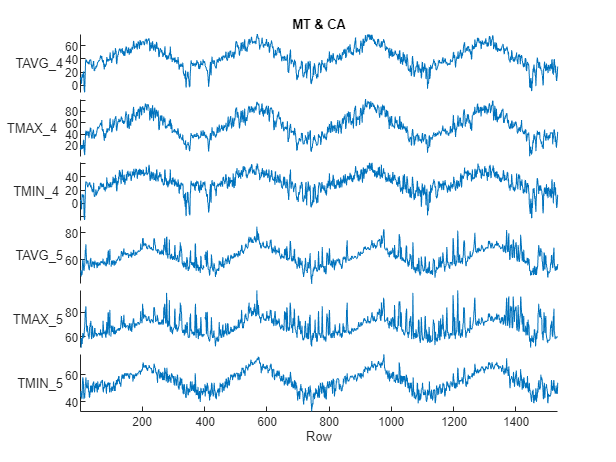


% 4 KALISPELL GLACIER AIRPORT, MT US
% 5 CARLSBAD MCCLELLAN PALOMAR AIRPORT, CA US
stackedplot(ws1(:,14:19))
title("MT & CA")

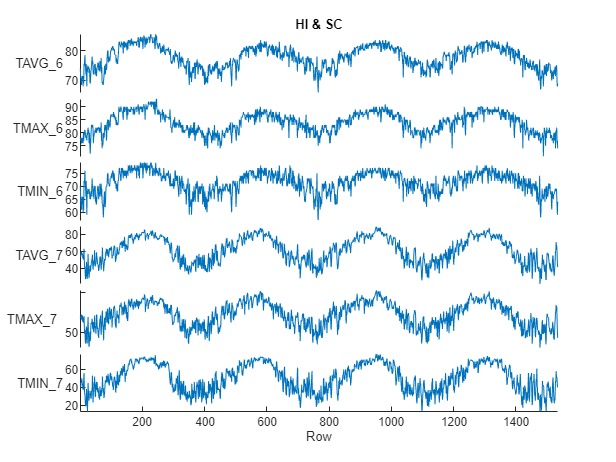


% 6 HONOLULU INTERNATIONAL AIRPORT, HI US
% 7 ANDERSON FAA AIRPORT, SC US
stackedplot(ws1(:,20:25))
title ("HI & SC")

 
% () Gaussian Process Regression (GPR) Rational Quadratic 
[trainedModel, vRMSE] = trainRegressionModelRQGPR(ws1);     % Train model
yfit = trainedModel.predictFcn(ws2);                        % Predict values
err = yfit - ws2.TAVG_2;                                    % Error

% (1) GPR Squared Exponential 
[trainedModel1, vRMSE1] = trainRegressionModelSEGPR(ws1);
yfit1 = trainedModel1.predictFcn(ws2);
err1 = yfit1 - ws2.TAVG_2;

% (2) Linear Regression (Linear)
[trainedModel2, vRMSE2] = trainRegressionModelLRL(ws1);

yfit2 = trainedModel2.predictFcn(ws2);
err2 = yfit2 - ws2.TAVG_2;

% (3) Linear SVM
[trainedModel3, vRMSE3] = trainRegressionModelSVM(ws1);
yfit3 = trainedModel3.predictFcn(ws2);
err3 = yfit3 - ws2.TAVG_2;

% (4) Linear Regression Robust Linear
[trainedModel4, vRMSE4] = trainRegressionModelRLR(ws1);

yfit4 = trainedModel4.predictFcn(ws2);
err4 = yfit4 - ws2.TAVG_2;


 
% Validation RMSE
vRMSE;vRMSE1;vRMSE2;vRMSE3;vRMSE4;
format shortE;Validate_RMSE = table(vRMSE,vRMSE1,vRMSE2,vRMSE3,vRMSE4);
Validate_RMSE.Properties.VariableNames = {'pred','pred1','pred2','pred3','pred4'}

Validate_RMSE = 1×5 table
       pred         pred1         pred2         pred3         pred4   
    __________    __________    __________    __________    __________

    8.5098e-05    8.5209e-05    2.3242e-14    1.0489e+00    2.6146e-14


format default;

% Average Error
avgError = mean(err,"all","double","omitnan");
avgError1 = mean(err1,"all","double","omitnan");
avgError2 = mean(err2,"all","double","omitnan");
avgError3 = mean(err3,"all","double","omitnan");
avgError4 = mean(err4,"all","double","omitnan");

%RMSE
format shortE;RMSE = [RMSE1,RMSE2,RMSE3,RMSE4,RMSE5]

RMSE =    8.5293e-05   8.5200e-05   2.3953e-14   1.7158e-14   1.0571e+00


%Predictions
format default;yfit = [yfit1,yfit2,yfit3,yfit4,yfit5]

yfit =    48.9999   49.0000   47.6835   49.0000   47.6858
   59.4998   59.5000   57.5117   59.5000   57.5174
   66.4998   66.5000   63.2784   66.5000   63.2887
   52.9999   53.0000   51.9586   53.0000   51.9668
   51.5000   51.5000   50.5277   51.5000   50.5275
   53.0000   53.0000   52.7661   53.0000   52.7616
   62.4999   62.5000   60.7273   62.5000   60.7259
   62.4999   62.5000   61.3150   62.5000   61.3088
   65.9998   66.0000   64.1072   66.0000   64.1018
   52.5000   52.5000   51.7363   52.5000   51.7369


err = [err1,err2,err3,err4,err5]

err =    -0.0001   -0.0000   -1.3165   -0.0000   -1.3142
   -0.0002   -0.0000   -1.9883   -0.0000   -1.9826
   -0.0002   -0.0000   -3.2216   -0.0000   -3.2113
   -0.0001   -0.0000   -1.0414         0   -1.0332
   -0.0000   -0.0000   -0.9723   -0.0000   -0.9725
   -0.0000   -0.0000   -0.2339         0   -0.2384
   -0.0001   -0.0000   -1.7727   -0.0000   -1.7741
   -0.0001   -0.0000   -1.1850         0   -1.1912
   -0.0002    0.0000   -1.8928         0   -1.8982
   -0.0000   -0.0000   -0.7637         0   -0.7631



xvals=[];
for i = 1:657
    x = mean(yfit(i,1:5),"all","omitnan");
    x1 = x;
    xvals(length(xvals)+1,1) = x1;
end
avgYfit = xvals;
difference = avgYfit - ws2.TAVG_2;
compr = [ws2.TAVG_2, avgYfit, difference]

compr =    49.0000   48.4738   -0.5262
   59.5000   58.7058   -0.7942
   66.5000   65.2134   -1.2866
   53.0000   52.5851   -0.4149
   51.5000   51.1110   -0.3890
   53.0000   52.9055   -0.0945
   62.5000   61.7906   -0.7094
   62.5000   62.0247   -0.4753
   66.0000   65.2418   -0.7582
   52.5000   52.1946   -0.3054


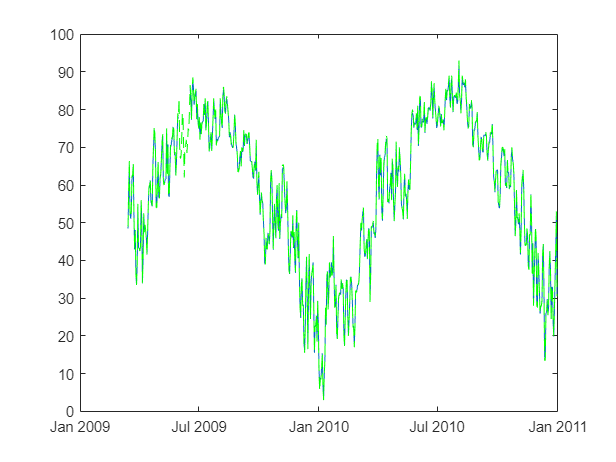


plot(ws2.DATE,avgYfit,ws2.DATE,ws2.TAVG_2,'g--')

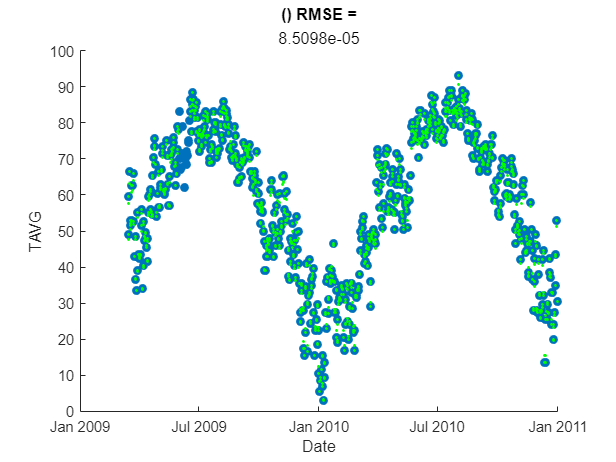

 
date = ws2.DATE;
tavg2 = ws2.TAVG_2;
scatter(ws2,"DATE","TAVG_2",'filled')
hold on
plot(date,yfit,'g.')
title("() RMSE =",vRMSE); xlabel("Date");ylabel("TAVG");
hold off

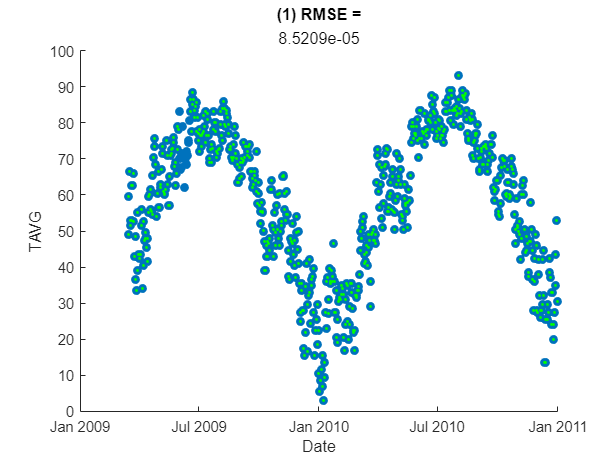



scatter(ws2,"DATE","TAVG_2",'filled')
hold on
plot(date,yfit1,'g.')
title("(1) RMSE =",vRMSE1); xlabel("Date");ylabel("TAVG");
hold off

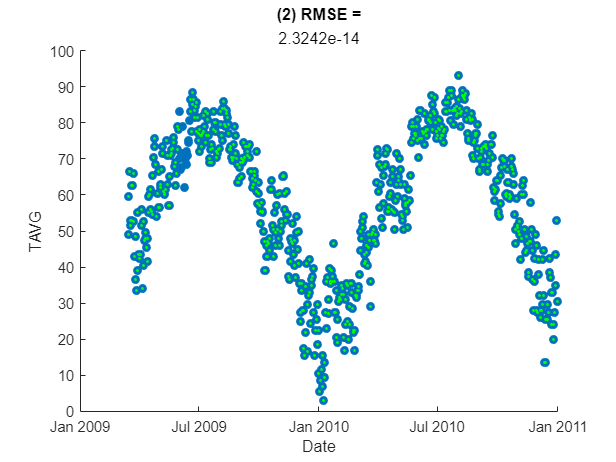



scatter(ws2,"DATE","TAVG_2",'filled')
hold on
plot(date,yfit2,'g.')
title("(2) RMSE =",vRMSE2); xlabel("Date");ylabel("TAVG");
hold off

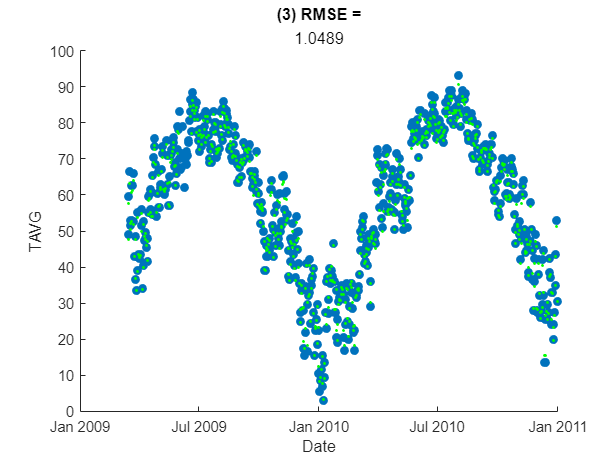



scatter(ws2,"DATE","TAVG_2",'filled')
hold on
plot(date,yfit3,'g.')
title("(3) RMSE =",vRMSE3); xlabel("Date");ylabel("TAVG");
hold off

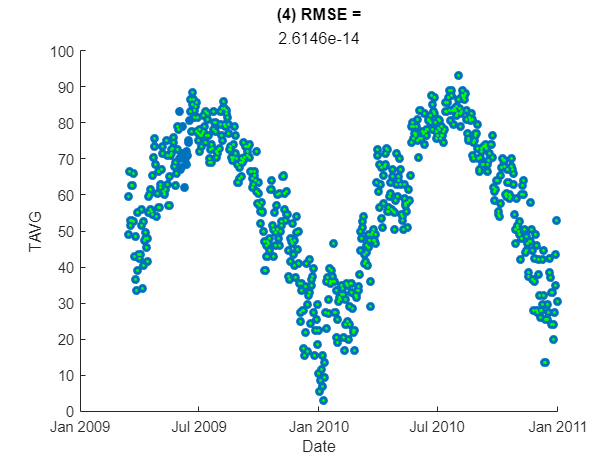



scatter(ws2,"DATE","TAVG_2",'filled')
hold on
plot(date,yfit4,'g.')
title("(4) RMSE =",vRMSE4); xlabel("Date");ylabel("TAVG");
hold off

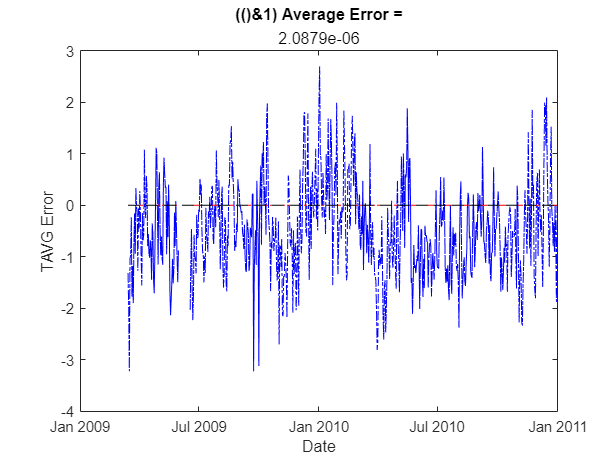


avgErr = (avgError + avgError1)./2;
avgErr2 = (avgError2 + avgError4)./2;
plot(date,err,'b-.',date,err1,'r-.',date,tavg2-tavg2,'k--')
title("(()&1) Average Error =",avgErr); xlabel("Date"); ylabel("TAVG Error");

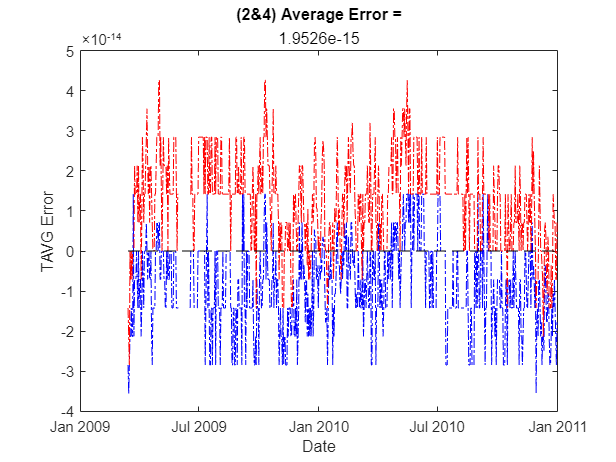

plot(date,err2,'b-.',date,err4,'r-.',date,tavg2-tavg2,'k--')
title("(2&4) Average Error =",avgErr2); xlabel("Date");ylabel("TAVG Error");

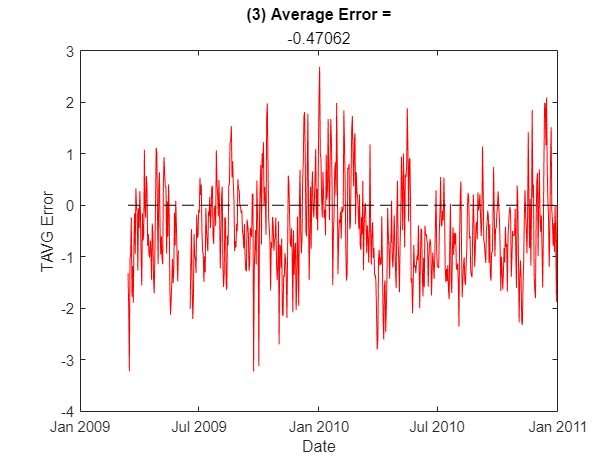

plot(date,err3,'r-',date,tavg2-tavg2,'k--')
title("(3) Average Error =",avgError3); xlabel("Date");ylabel("TAVG Error");

 
% () Gaussian Process Regression (GPR) Rational Quadratic 
tavg2 = ws2.TAVG_2;
yfit = trainedModel.predictFcn(ws2);
err = yfit - ws2.TAVG_2;
% (1) GPR Squared Exponential 

yfit1 = trainedModel1.predictFcn(ws2);
err1 = yfit1 - ws2.TAVG_2;
% (2) Linear Regression (Linear)

yfit2 = trainedModel2.predictFcn(ws2);
err2 = yfit2 - ws2.TAVG_2;
% (3) Linear SVM

yfit3 = trainedModel3.predictFcn(ws2);
err3 = yfit3 - ws2.TAVG_2;
% (4) Linear Regression Robust Linear

yfit4 = trainedModel4.predictFcn(ws2);
err4 = yfit4 - ws2.TAVG_2;



Predictions = table(tavg2,yfit,yfit1,yfit2,yfit3,yfit4);
Predictions.Properties.VariableNames = {'Tavg','pred','pred1','pred2','pred3','pred4'}

Predictions = 657×6 table
    Tavg    pred    pred1    pred2    pred3     pred4
    ____    ____    _____    _____    ______    _____

      49      49      49       49     47.683      49 
    59.5    59.5    59.5     59.5     57.512    59.5 
    66.5    66.5    66.5     66.5     63.278    66.5 
      53      53      53       53     51.959      53 
    51.5    51.5    51.5     51.5     50.528    51.5 
      53      53      53       53     52.766      53 
    62.5    62.5    62.5     62.5     60.727    62.5 
    62.5    62.5    62.5     62.5     61.315    62.5 
      66      66      66       66     64.107      66 
    52.5    52.5    52.5     52.5     51.736    52.5 
      43      43      43       43     42.843      43 
    48.5    48.5    48.5     48.5     47.559    48.5 
    36.5    3

 
% () Gaussian Process Regression (GPR) Rational Quadratic 
[trainedModel, vRMSE] = trainRegressionMdl_ratquadGPR(ws1)     % Train model

trainedModel = struct with fields:
           predictFcn: @(x)gpPredictFcn(predictorExtractionFcn(x))
    RequiredVariables: {'TAVG'  'TAVG_1'  'TAVG_3'  'TAVG_4'  'TAVG_5'  'TAVG_6'  'TAVG_7'  'TMAX'  'TMAX_1'  'TMAX_3'  'TMAX_4'  'TMAX_5'  'TMAX_6'  'TMAX_7'  'TMIN'  'TMIN_1'  'TMIN_3'  'TMIN_4'  'TMIN_5'  'TMIN_6'  'TMIN_7'}
         RegressionGP: [1×1 RegressionGP]
                About: 'This struct is a trained model exported from Regression Learner R2021b.'
         HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to pred

vRMSE = 6.7604

% (1) GPR Exponential 
[trainedModel1, vRMSE1] = trainRegressionMdl_expGPR(ws1)

trainedModel1 = struct with fields:
           predictFcn: @(x)gpPredictFcn(predictorExtractionFcn(x))
    RequiredVariables: {'TAVG'  'TAVG_1'  'TAVG_3'  'TAVG_4'  'TAVG_5'  'TAVG_6'  'TAVG_7'  'TMAX'  'TMAX_1'  'TMAX_3'  'TMAX_4'  'TMAX_5'  'TMAX_6'  'TMAX_7'  'TMIN'  'TMIN_1'  'TMIN_3'  'TMIN_4'  'TMIN_5'  'TMIN_6'  'TMIN_7'}
         RegressionGP: [1×1 RegressionGP]
                About: 'This struct is a trained model exported from Regression Learner R2021b.'
         HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to pre

vRMSE1 = 6.7769

% (2) GPR Squared Exponential
[trainedModel2, vRMSE2] = trainRegressionMdl_sqrExpGPR(ws1);
% (3) SVM Medium Gaussian
[trainedModel3, vRMSE3] = trainRegressionMdl_medGausSVM(ws1);
% (4) GPR Matern 5/2
[trainedModel4, vRMSE4] = trainRegressionMdl_matrn52GPR(ws1);


 
% () Gaussian Process Regression (GPR) Rational Quadratic (RQ)
yft = trainedModel.predictFcn(ws2);                        % Predict values
er = yfit - ws2.TAVG_2;                                    % Error

% (1) GPR Exponential (EXP)
yft1 = trainedModel1.predictFcn(ws2);
er1 = yfit1 - ws2.TAVG_2;

% (2) GPR Squared Exponential (sEXP)
yft2 = trainedModel2.predictFcn(ws2);
er2 = yfit2 - ws2.TAVG_2;

% (3) SVM Medium Gaussian (SVM)
yft3 = trainedModel3.predictFcn(ws2);
er3 = yfit3 - ws2.TAVG_2;

% (4) GPR Matern 5/2  (M52)
yft4 = trainedModel4.predictFcn(ws2);
er4 = yfit4 - ws2.TAVG_2;


 
PredictionRMSE = table(vRMSE,vRMSE1,vRMSE2,vRMSE3,vRMSE4);
PredictionRMSE.Properties.VariableNames = {'RMSE','RMSE1','RMSE2','RMSE3','RMSE4'}

PredictionRMSE = 1×5 table
     RMSE     RMSE1     RMSE2     RMSE3     RMSE4 
    ______    ______    ______    ______    ______

    6.7604    6.7769    6.8774    6.9106    6.8327



Predictions = table(tavg2,yft,yft1,yft2,yft3,yft4);
Predictions.Properties.VariableNames = {'Tavg','pred','pred1','pred2','pred3','pred4'}

Predictions = 657×6 table
    Tavg     pred     pred1     pred2     pred3     pred4 
    ____    ______    ______    ______    ______    ______

      49      39.9    40.163    40.191    38.869    40.009
    59.5    42.787    42.413    43.261    43.374    42.893
    66.5     43.81    43.939    44.768    45.495    44.668
      53     43.32    43.445    45.587    44.991     44.61
    51.5    51.004    50.611    49.878    50.835    49.993
      53    49.175    49.769    50.433    49.995    50.464
    62.5    49.899    49.458    49.715     48.91    49.248
    62.5    54.046    53.817    53.407    52.435    53.268
      66     49.94    50.007    50.497    49.785    50.299
    52.5    47.182    46.984    48.751    47.421    47.722
      43    42.518    42.511    44.538     43.02    43.181
  


PredictionError = table(tavg2,er,er1,er2,er3,er4);
PredictionError.Properties.VariableNames = {'Tavg','Error','Error1','Error2','Error3','Error4'}

PredictionError = 657×6 table
    Tavg       Error         Error1         Error2        Error3        Error4   
    ____    ___________    ___________    ___________    _________    ___________

      49     -8.464e-05     -8.455e-05    -2.8422e-14      -1.3165    -1.4211e-14
    59.5    -0.00015229    -0.00015221    -3.5527e-14      -1.9883    -2.1316e-14
    66.5    -0.00021092    -0.00021078    -2.8422e-14      -3.2216    -2.8422e-14
      53     -8.236e-05    -8.2426e-05    -2.1316e-14      -1.0414              0
    51.5    -4.1777e-05    -4.1634e-05    -2.1316e-14     -0.97229    -7.1054e-15
      53    -3.9579e-05    -3.9548e-05    -1.4211e-14     -0.23388              0
    62.5    -0.00010458    -0.00010444    -2.1316e-14      -1.7727    -7.1054e-15
    62.5     -6.652e-05    

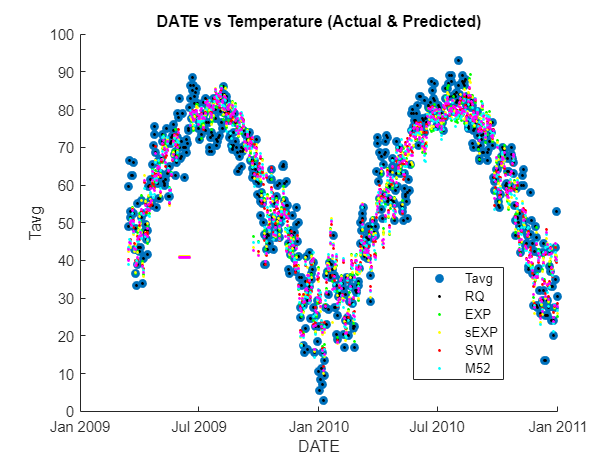

 
scatter(date,tavg2,'filled')
hold on
plot(date,tavg2,'k.',date,yft,'g.',date,yft1,'y.',date,yft2,'r.',date,yft3,'c.',date,yft4,'m.')
title("DATE vs Temperature (Actual & Predicted)");xlabel("DATE");ylabel("Tavg");
legend('Tavg','RQ','EXP','sEXP','SVM','M52');legend('Position',[0.6717,0.20361,0.14643,0.19286]);
hold off

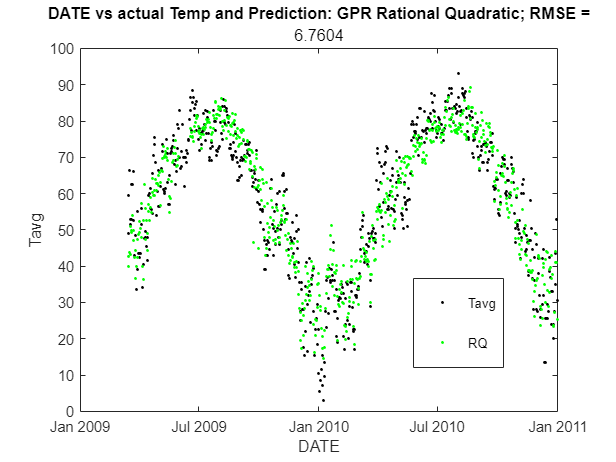


plot(date,tavg2,'k.',date,yft,'g.')
title("DATE vs actual Temp and Prediction: GPR Rational Quadratic; RMSE =",vRMSE);xlabel("DATE");ylabel("Tavg");
legend('Tavg','RQ');legend('Position',[0.6717,0.20361,0.14643,0.19286]);

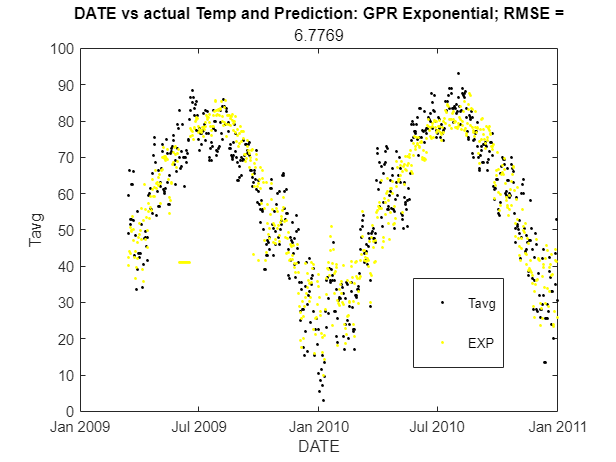


plot(date,tavg2,'k.',date,yft1,'y.')
title("DATE vs actual Temp and Prediction: GPR Exponential; RMSE =",vRMSE1);xlabel("DATE");ylabel("Tavg");
legend('Tavg','EXP');legend('Position',[0.6717,0.20361,0.14643,0.19286]);

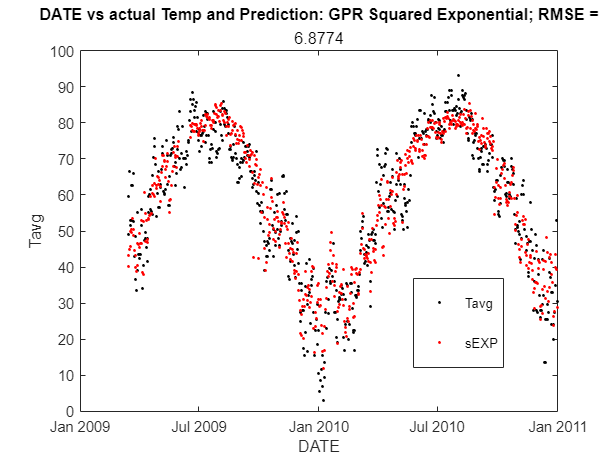


plot(date,tavg2,'k.',date,yft2,'r.')
title("DATE vs actual Temp and Prediction: GPR Squared Exponential; RMSE =",vRMSE2);xlabel("DATE");ylabel("Tavg");
legend('Tavg','sEXP');legend('Position',[0.6717,0.20361,0.14643,0.19286]);

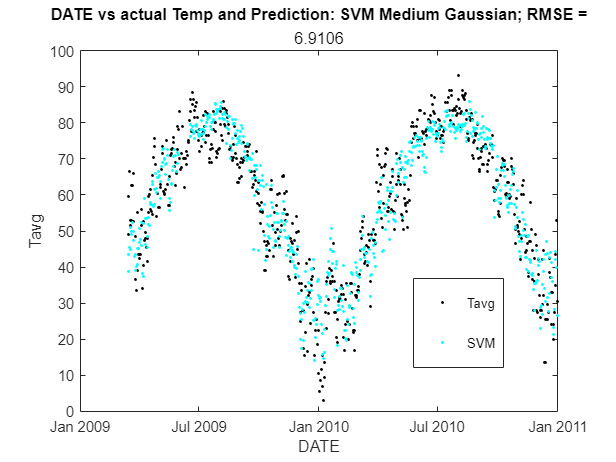


plot(date,tavg2,'k.',date,yft3,'c.')
title("DATE vs actual Temp and Prediction: SVM Medium Gaussian; RMSE =",vRMSE3);xlabel("DATE");ylabel("Tavg");
legend('Tavg','SVM');legend('Position',[0.6717,0.20361,0.14643,0.19286]);

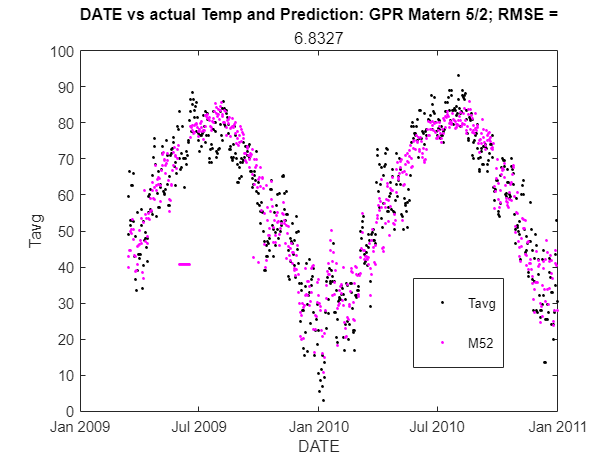


plot(date,tavg2,'k.',date,yft4,'m.')
title("DATE vs actual Temp and Prediction: GPR Matern 5/2; RMSE =",vRMSE4);xlabel("DATE");ylabel("Tavg");
legend('Tavg','M52');legend('Position',[0.6717,0.20361,0.14643,0.19286]);